% EI_oscillator.m
%
% Firing rate model for two populations, one excitatory and one inhibitory,
% coupled to produce a PING oscillator with a firing-rate model.
%
% The code calculates the oscillation frequency using two methods, one via
% a Fourier transform. 
%
% Different baseline currents are used and the frequency-dependence is
% plotted.
%
% This code was used to generate Figure 6.14 of the textbook
% An Introductory Course in Computational Neuroscience
% by Paul Miller (Brandeis University, 2017)
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;

## Set up the simulation parameters

dt = 0.0001;                 % Time step to use
tmax = 1.5;                   % Maximum time for simulation
tvec = dt:dt:tmax;           % Vector of time points
Nt = length(tvec);           % Number of time points
N_Units = 2;

## Parameters for firing-rate response curve which is the model by

delta_V = 0.030;            % Threshold voltage minus reset voltage
% The parameters a and sigma_V both set the curvature of firing rate curve.
% sigma_V should be the standard deviation of voltage noise and then gets
% scaled (inversely) by a. Here sigma_V does not actually add noise
% fluctuations unless the flag V_noise_on_flag is set to 1.
a = 1;
sigma_V = 0.001;
Vth = -0.050;               % Threshold voltage (V)
E_L = -0.070;               % Leak voltage (V)
G_L = 0.05e-9;                 % Leak conductance (nS)
E_I = -0.065;               % Inhibitory synapse reversal potential (V)
tau = 0.003;                % Time constant for firing-rate to change

## Parameters that vary across conditions are given in vectors, with each

## Synaptic response parameters

alpha0 = 0.2;           % Baseline postsynaptic amplitude.
Wee = 25e-9;               % Strength of E-to-E synaptic feedback.
Wei = 4e-9;               % Strength of E-to-I synaptic feedback.
Wie = 800e-9;              % Strength of I-to-E synaptic feedback.
Wii = 0;                % Strength of I-to-I synaptic feedback.

tau_sE = 0.002;                 % Synaptic time constant for E-feedback
tau_sI = 0.005;                 % Synaptic time constant for I-feedback

## Stimulus properties that vary per trial

t_on = dt;                          % Time of stimulus onset

% Mean excitatory input conductance to E-Unit (1)
G_E_input_vec = [0:2:10.0]*1e-9;%was [0:0.2:10.0]*1e-9;
%G_E_input_vec = 1e-9;
% Mean excitatory input conductance to I-Unit (2)
G_I_input_vec = zeros(size(G_E_input_vec));

stim_length = tmax-t_on;            % Duration of stimulus

## Set up variables to record results

Nparameters is the number of different parameter sets where each parameter set here contains one value for the input to the circuit

Nparameters = length(G_E_input_vec);

mean_f = zeros(1,Nparameters);
Num_cycles = zeros(1,Nparameters);
r_amp1 = zeros(1,Nparameters);
r_amp2 = zeros(1,Nparameters);
mean_r1 = zeros(1,Nparameters);
mean_r2 = zeros(1,Nparameters);
f_alt = zeros(1,Nparameters);
A = zeros(1,Nparameters);
B = zeros(1,Nparameters);

for parameter = 1:Nparameters           % Loop through stimulus values
    parameter           % Prints to screen to indicate progress
    
    sum_times = 0;          % Initialize for this stimulus set
    sum_sqr_times = 0;      % Initialize for this stimulus set
    % The variable "counts" accumulates the number of times each unit crosses
    % threshold first
    counts = zeros(1,2);    % Initialize to zero for this stimulus set
    
    Wee_mat = [Wee 0; Wei 0];   % Matrix of E-to-E synaptic strengths
    Wei_mat = [0 Wie; 0 Wii];   % Matrix of E-to-I synaptic strengths
    
    % G_input1 is amplitude of excitatory input to Unit 1
    G_input1 = G_E_input_vec(parameter);
    % G_input2 is amplitude of excitatory input to Unit 2
    G_input2 = G_I_input_vec(parameter);
    
    G_stim = zeros(N_Units, Nt);        % Initialize vector for the stimulus
    % then add stimulus to appropriate time points.
    t_off = t_on + stim_length;         % Time for stimulus offset
    G_stim(1,round(t_on/dt):round(t_off/dt)) = G_input1;
    G_stim(2,round(t_on/dt):round(t_off/dt)) = G_input2;
    
    % Below is the formula for the firing rate response function that will
    % be used in both the steady state curves and the simulation.
    % This is a function of "x" where "x" is the value of the
    % variable (or vector of values) sent to the function.
    r_of_Vss = @(x) (x - Vth)./(tau*delta_V*(1-exp(-a*(x-Vth)/sigma_V)));
    
    % To prevent division by zero when x = Vth, use the limit
    % value:
    r_of_Vss_limit = 1./(tau*delta_V*a/sigma_V);
    
    r = zeros(N_Units,Nt);        % Initialize vector for firing rates
    sE = zeros(N_Units,Nt);       % Initialize vector for synaptic inputs
    sI = zeros(N_Units,Nt);       % Initialize vector for synaptic inputs

parameter = 1

parameter = 2

parameter = 3

parameter = 4

parameter = 5

parameter = 6

## Now carry simulate the same model as a function of time

In models with multiple variables, each variable is updated using the values of the set of variables on the previous time step

    % A while loop is used to exit the trial once threshold is
    % reached
    for i =2:Nt
        
        % Calculate the steady-state membrane potential for a
        % leaky-integrate-and-fire cell based on the excitatory and
        % inhibitory synaptic inputs.
        % Vss is a column vector with one value for each cell.
        % The synaptic inputs are obtained by matrix multiplication
        % using the connectivity matrices Wee_mat and Wei_mat, plus
        % the stimulus input conductance in "stim".
        Vss = (E_L*G_L +E_I*Wei_mat*sI(:,i-1) )./ ...
            (G_L  + Wee_mat*sE(:,i-1) + Wei_mat*sI(:,i-1) +G_stim(:,i));
        
        % Now update the firing rate using the equation
        % dr/dt = -(r + r(Vss) )/tau
        for cell = 1:N_Units
            if ( Vss(cell) == Vth )
                r(cell,i) = r(cell,i-1)*(1-dt/tau) + ...
                    dt/tau*r_of_Vss_limit;
            else
                r(cell,i) = r(cell,i-1)*(1-dt/tau) + ...
                    dt/tau*r_of_Vss(Vss(cell));
            end
        end
        
        % Next update the synaptic response variable,s, which depends on
        % all of rate, facilitation and depression variables, using the
        % equation
        % ds/dt = -s/tau_s + alpha.r.(1-s)
        sE(:,i) = sE(:,i-1)*(1-dt/tau_sE) + ...
            dt*alpha0.*r(:,i-1).*(1-sE(:,i-1));
        
        % The inhibitory synapti response differs because of the
        % different time constant.
        sI(:,i) = sI(:,i-1)*(1-dt/tau_sI) + ...
            dt*alpha0.*r(:,i-1).*(1-sI(:,i-1));
    end;        % go to next time point
    
   [f_alt,mean_f]=calcOscillations(tvec,dt,r,parameter,mean_f);
    
end;            % Go to next parameter set and produce a new trial

## Set up the plotting parameters and plot the results

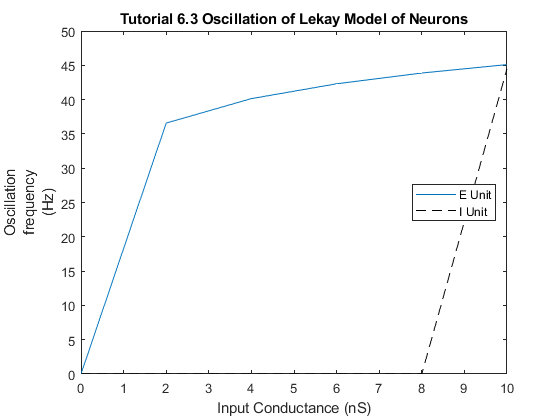

plotXY(1e9*G_E_input_vec, mean_f,'Tutorial 6.3 Oscillation of Lekay Model of Neurons','Input Conductance (nS)',{'Oscillation'; 'frequency'; '(Hz)'},true);
hold on;
plot(1e9*G_E_input_vec, f_alt,'k--');
legend('E Unit', 'I Unit','Location','best')

## Calculate oscillation frequency

function [f_alt,mean_f]=calcOscillations (tvec,dt,r,parameter,mean_f)
    % We want to ignore the initial transient before oscillations are
    % periodic.
    t_transient = 0.5;                      % Time of transient to ignore
    N_transient = round(t_transient/dt);    % Number of time bins to ignore
    r_calc1 = r(1,N_transient:end);         % Cell 1's rate after transient
    r_calc2 = r(2,N_transient:end);         % Cell 2's rate after transient
    N_calc = length(r_calc1);               % Number of time bins after transient
    
    r_peak1 = max(r_calc1);                 % Maximum of r1 oscillations
    r_min1 = min(r_calc1);                  % Minimum of r1 oscillations
    r_peak2 = max(r_calc2);                 % Maximum of r2 oscillations
    r_min2 = min(r_calc2);                  % Minimum of r2 oscillations
    
    r_amp1(parameter) = r_peak1-r_min1;     % Amplitude of r1 oscillations
    r_amp2(parameter) = r_peak2-r_min2;     % Amplitude of r2 oscillations
    
    % In case of noise we set two thresholds, one "r_thresh_high" for
    % approaching the peak from below and the other, "r_thresh_low" for
    % approaching the trough from above. To record a new oscillation a
    % crossing from low-to-high is needed after an intervening crossing
    % from high-to-low. Cell 1 is used.
    r_thresh_high = 0.75*r_peak1 + 0.25*r_min1; % 3/4 from trough to peak
    r_thresh_low = 0.25*r_peak1 + 0.75*r_min1;  % 1/4 from trough to peak
    
    if ( r_calc1(1) > r_thresh_high )       % If initially in the peak
        in_peak = 1;                        % Set the variable to 1
    else;                                   % Otherwise
        in_peak = 0;                        % Set the variable to 0
    end
    
    N_peaks = 0;                            % Number of peak crossings
    t_cross = [];                           % Times of peak crossings
    
    for i = 2:N_calc;                       % Loop through time points
        
        % If not already in a peak and now the rate crosses the high
        % threshold for entering into a peak:
        if ( ~in_peak && ( r_calc1(i) > r_thresh_high ) )
            in_peak = 1;                    % Signal being in a peak
            N_peaks = N_peaks + 1;          % Accumulate new peak crossing
            t_cross(N_peaks) = i;           % Time-bin of new peak crossing
        else
            % Otherwise if in a peak and now the rate drops below the low
            % threshold for entering into a trough
            if ( ( in_peak ) && ( r_calc1(i) < r_thresh_low ) )
                in_peak = 0;                % Signal being out of a peak
            end
        end
    end;                                % Finish looping through time bins
    
    Num_cycles(parameter) = N_peaks;    % Total number of peak crossings
    if ( N_peaks > 1 )                  % Must be > 1 to calculate period
        % The mean frequency is 1/(Mean Period) where Mean Period is time
        % between the last crossing and the first crossing into a peak
        % divided by one less than the number of such crossings
        mean_f(parameter) = 1/(dt*(t_cross(N_peaks) - t_cross(1))/(N_peaks - 1));
    end
    mean_r1(parameter) = mean(r_calc1);     % Mean firing rate of cell 1
    mean_r2(parameter) = mean(r_calc2);     % Mean firing rate of cell 2
%Now produce a power spectrum to find frequency by an alternative method
%This method tests cosines and sines of different frequencies to see
%which frequency is the most correlated with the firing rate.
%This is essentially the Fourier Transform.
    f_vec = 0:0.5:100;          % Set of frequencies to test
    Nf = length(f_vec);         % Number of distinct frequencies
    for i = 1:Nf;               % Loop through set of frequencies
        f = f_vec(i);           % Value of frequency to test
        sinvec = sin(2*pi*f*tvec);      % sine function at that frequency
        cosvec = cos(2*pi*f*tvec);      % cosine function at that frequency
        
        % Now take the normalized dot produce of the sine function then the
        % cosine function with the firing rate vector.
        sin_overlap = mean(sinvec.*r(1,:));
        cos_overlap = mean(cosvec.*r(1,:));
        
        A(i) = sin_overlap;
        B(i) = cos_overlap;
    end
    % The power spectrum is given by the sum of the squares of the two
    % coefficients (sine coefficients, A, and cosine coefficients, B).
    % This essentially works because sin(x)*sin(x) + cos(x)*cos(x) = 1 for
    % all x.
    power = A.*A + B.*B;

    [maxpower ,f_index] = max(power(2:end));
    f_alt(parameter) = f_vec(f_index);
 end